clc
clear all;

The electrical initial states of your model are forced to steady state by the powergui block.
Found algebraic loop containing: 
IDTmodel/4MVA SG1/B_7 MAN 5000 MVA1/Electrical model/Synchronous Machine Discrete Model/phi/Product1
IDTmodel/4MVA SG1/B_7 MAN 5000 MVA1/Electrical model/Synchronous Machine Discrete Model/phi/Ad*x(k-1) + Bd*( u(k-1) + u(k))
IDTmodel/4MVA SG1/B_7 MAN 5000 MVA1/Electrical model/Synchronous Machine Discrete Model/phi/IC (discontinuity)


fileName = '1.jpg'

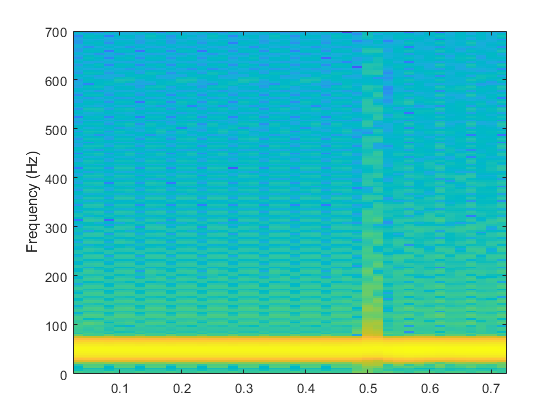

The electrical initial states of your model are forced to steady state by the powergui block.
Found algebraic loop containing: 
IDTmodel/4MVA SG1/B_7 MAN 5000 MVA1/Electrical model/Synchronous Machine Discrete Model/phi/Product1
IDTmodel/4MVA SG1/B_7 MAN 5000 MVA1/Electrical model/Synchronous Machine Discrete Model/phi/Ad*x(k-1) + Bd*( u(k-1) + u(k))
IDTmodel/4MVA SG1/B_7 MAN 5000 MVA1/Electrical model/Synchronous Machine Discrete Model/phi/IC (discontinuity)


fileName = '2.jpg'

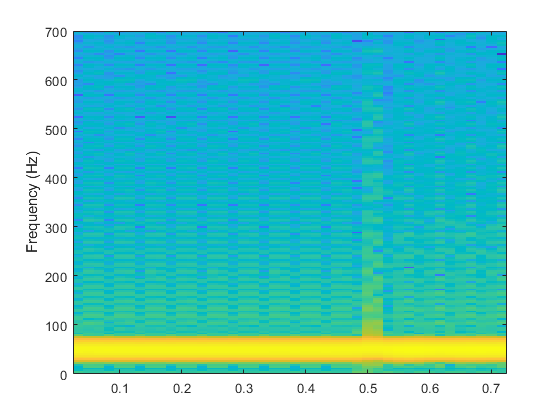

warning('off', 'all');
bas=2e6;
for k= 1:2
sim('IDTmodel');
Va= VoltageCB1a.Data(1:end);
% Parameters
fs = 3840;  % Sampling frequency in Hz
window_length = 256;  % Window length for STFT
overlap = 192;  % Overlap between windows
nfft = 1024;  % Number of FFT points

% Perform STFT and create spectrograms for each phase
figure;
% Compute STFT
[S, F, T] = spectrogram(Va, window_length, overlap, nfft, fs, 'yaxis');

% Plot spectrogram
imagesc(T, F, 10*log10(abs(S)));
axis xy;
ylabel('Frequency (Hz)');
ylim([0 700]);
% title(['Phase ', num2str(phase), ' Spectrogram']);
% colorbar;
% Create your figure
% plot(x, y);

% Specify the full path and filename
folderPath = 'C:\Users\Dell\Desktop\Project MSC Third Sem\Papers\MATLAB Files\Scripts\Datasets\Islanding';
fileName= [ num2str(k) '.jpg']
fullPath = fullfile(folderPath, fileName);
saveas(gcf, fullPath);
bas=3e6;
end